%% COMPREHENSIVE_ANALYSIS_V2.M - 交互式声纹特征分析工具 (最终版)

% -------------------------------------------------------------------------
% 功能: 引导用户输入两组音频文件/文件夹，计算内部一致性、外部区分度并生成报告。
% 依赖文件: 
% 1. extract_voice_features.m (特征提取主函数)
% 2. feature_analysis_tool.m (两文件距离计算函数)
% -------------------------------------------------------------------------

clear; close all; clc;
disp('==================================================');

disp('  ✅ 交互式声纹特征分析工具 (已集成Python预处理流程) ✅');

  ✅ 交互式声纹特征分析工具 (已集成Python预处理流程) ✅


disp('==================================================');


% ------------------------ 1. 交互式获取文件列表 ------------------------

% 获取 Speaker A (同一个人) 文件列表
try
    Files_A = get_file_list('同一个人 (Speaker A)');
catch ME
    disp(ME.message);
    return; % 终止脚本
end

成功获取 15 个 同一个人 (Speaker A) 的音频文件。



% 获取 Speaker B (另一个人) 文件列表
try
    Files_B = get_file_list('另一个人 (Speaker B)');
catch ME
    disp(ME.message);
    return; % 终止脚本
end

成功获取 29 个 另一个人 (Speaker B) 的音频文件。



% ------------------------ 2. 初始化结果存储 ------------------------

FinalResultsTable = cell(0, 3);
row_index = 1;
InternalDistances = [];
ExternalDistances = [];
count_A = length(Files_A);
count_B = length(Files_B);

if count_A < 2 || count_B < 1
    error('错误：Speaker A 至少需要 2 个文件，Speaker B 至少需要 1 个文件才能进行对比。');
end


% ------------------------ 3. 阶段 1: 内部一致性计算 (A vs A) ------------------------

disp(' ');

disp('--- 阶段 1: 内部一致性计算 (A vs A) ---');

--- 阶段 1: 内部一致性计算 (A vs A) ---


total_internal_pairs = count_A * (count_A - 1) / 2;
disp(['总共需要计算 ', num2str(total_internal_pairs), ' 组内部对比。']);

总共需要计算 105 组内部对比。



for i = 1:count_A
    file_A = Files_A{i};
    for j = i + 1:count_A
        file_B = Files_A{j};
        
        fprintf('  > Calculating Internal: %s vs %s...\n', file_A, file_B);
        
        try
            % 调用 feature_analysis_tool
            current_distance = feature_analysis_tool(file_A, file_B);
            
            % 存储结果
            FinalResultsTable{row_index, 1} = [file_A, ' vs ', file_B];
            FinalResultsTable{row_index, 2} = current_distance;
            FinalResultsTable{row_index, 3} = 'Internal (A vs A)';
            
            InternalDistances = [InternalDistances, current_distance];
            row_index = row_index + 1;
            
        catch ME
            warning(['内部计算失败: ', ME.message, '。 跳过此对。']);
        end
    end
end

  > Calculating Internal: E:\开放实验\语音库\LibriSpeech\dev-clean\1272\128104\1272-128104-0000.flac vs E:\开放实验\语音库\LibriSpeech\dev-clean\1272\128104\1272-128104-0001.flac...
  > Calculating Internal: E:\开放实验\语音库\LibriSpeech\dev-clean\1272\128104\1272-128104-0000.flac vs E:\开放实验\语音库\LibriSpeech\dev-clean\1272\128104\1272-128104-0002.flac...
  > Calculating Internal: E:\开放实验\语音库\LibriSpeech\dev-clean\1272\128104\1272-128104-0000.flac vs E:\开放实验\语音库\LibriSpeech\dev-clean\1272\128104\1272-128104-0003.flac...
  > Calculating Internal: E:\开放实验\语音库\LibriSpeech\dev-clean\1272\128104\1272-128104-0000.flac vs E:\开放实验\语音库\LibriSpeech\dev-clean\1272\128104\1272-128104-0004.flac...
  > Calculating Internal: E:\开放实验\语音库\LibriSpeech\dev-clean\1272\128104\1272-128104-0000.flac vs E:\开放实验\语音库\LibriSpeech\dev-clean\1272\128104\1272-128104-0005.flac...
  > Calculating Internal: E:\开放实验\语音库\LibriSpeech\dev-clean\1272\128104\1272-128104-0000.flac vs E:\开放实验\语音库\LibriSpeech\dev-clean\1272\128104\1272-128104-0006.



% ------------------------ 4. 阶段 2: 外部区分度计算 (A vs B) ------------------------

disp(' ');

disp('--- 阶段 2: 外部区分度计算 (A vs B) ---');

--- 阶段 2: 外部区分度计算 (A vs B) ---


total_external_pairs = count_A * count_B;
disp(['总共需要计算 ', num2str(total_external_pairs), ' 组外部对比。']);

总共需要计算 435 组外部对比。



for i = 1:count_A
    file_A = Files_A{i};
    for j = 1:count_B 
        file_B = Files_B{j};
        
        fprintf('  > Calculating External: %s vs %s...\n', file_A, file_B);
        
        try
            % 调用 feature_analysis_tool
            current_distance = feature_analysis_tool(file_A, file_B);
            
            % 存储结果
            FinalResultsTable{row_index, 1} = [file_A, ' vs ', file_B];
            FinalResultsTable{row_index, 2} = current_distance;
            FinalResultsTable{row_index, 3} = 'External (A vs B)';
            
            ExternalDistances = [ExternalDistances, current_distance];
            row_index = row_index + 1;
            
        catch ME
            warning(['外部计算失败: ', ME.message, '。 跳过此对。']);
        end
    end
end

  > Calculating External: E:\开放实验\语音库\LibriSpeech\dev-clean\1272\128104\1272-128104-0000.flac vs E:\开放实验\语音库\LibriSpeech\dev-clean\84\121123\84-121123-0000.flac...
  > Calculating External: E:\开放实验\语音库\LibriSpeech\dev-clean\1272\128104\1272-128104-0000.flac vs E:\开放实验\语音库\LibriSpeech\dev-clean\84\121123\84-121123-0001.flac...
  > Calculating External: E:\开放实验\语音库\LibriSpeech\dev-clean\1272\128104\1272-128104-0000.flac vs E:\开放实验\语音库\LibriSpeech\dev-clean\84\121123\84-121123-0002.flac...
  > Calculating External: E:\开放实验\语音库\LibriSpeech\dev-clean\1272\128104\1272-128104-0000.flac vs E:\开放实验\语音库\LibriSpeech\dev-clean\84\121123\84-121123-0003.flac...
  > Calculating External: E:\开放实验\语音库\LibriSpeech\dev-clean\1272\128104\1272-128104-0000.flac vs E:\开放实验\语音库\LibriSpeech\dev-clean\84\121123\84-121123-0004.flac...
  > Calculating External: E:\开放实验\语音库\LibriSpeech\dev-clean\1272\128104\1272-128104-0000.flac vs E:\开放实验\语音库\LibriSpeech\dev-clean\84\121123\84-121123-0005.flac...
  > Calculating 

        fprintf('  > Calculating External: %s vs %s...\n', file_A, file_B);

  > Calculating External: E:\开放实验\语音库\LibriSpeech\dev-clean\1272\128104\1272-128104-0014.flac vs E:\开放实验\语音库\LibriSpeech\dev-clean\84\121123\84-121123-0028.flac...



        try
            % 调用 feature_analysis_tool
            current_distance = feature_analysis_tool(file_A, file_B);

            % 存储结果
            FinalResultsTable{row_index, 1} = [file_A, ' vs ', file_B];
            FinalResultsTable{row_index, 2} = current_distance;
            FinalResultsTable{row_index, 3} = 'External (A vs B)';

            ExternalDistances = [ExternalDistances, current_distance];
            row_index = row_index + 1;

        catch ME
            warning(['外部计算失败: ', ME.message, '。 跳过此对。']);
        end



% ------------------------ 5. 汇总统计结果 ------------------------

disp(' ');

disp('==================================================');

disp('                📌分析统计结果');

                📌分析统计结果


disp('==================================================');


avg_internal = mean(InternalDistances);
avg_external = mean(ExternalDistances);

fprintf('\n内部一致性平均距离 (A vs A): %.4f\n', avg_internal);


内部一致性平均距离 (A vs A): 0.0469


fprintf('外部区分度平均距离 (A vs B): %.4f\n\n', avg_external);

外部区分度平均距离 (A vs B): 202.1266





% ------------------------ 6. 生成最终表格 ------------------------

ResultTable = cell2table(FinalResultsTable, ...
    'VariableNames', {'Pair', 'Distance', 'Type'});

disp(ResultTable);

                                                                             Pair                                                                              Distance            Type         
    _______________________________________________________________________________________________________________________________________________________    ________    _____________________

    {'E:\开放实验\语音库\LibriSpeech\dev-clean\1272\128104\1272-128104-0000.flac vs E:\开放实验\语音库\LibriSpeech\dev-clean\1272\128104\1272-128104-0001.flac'}    0.014925    {'Internal (A vs A)'}
    {'E:\开放实验\语音库\LibriSpeech\dev-clean\1272\128104\1272-128104-0000.flac vs E:\开放实验\语音库\LibriSpeech\dev-clean\1272\128104\1272-128104-0002.flac'}    0.029851    {'Internal (A vs A)'}
    {'E:\开放实验\语音库\LibriSpeech\dev-clean\1272\128104\1272-128104-0000.flac vs E:\开放实验\语音库\LibriSpeech\dev-clean\1272\128104\1272-128104-0003.flac'}    0.044776    {'Internal (A vs A)'}
    {'E:\开放实验\语音库\LibriSpeech\dev-clean\1272\128104\1272-1281



% ------------------------ 7. 自动输出结果到 CSV ------------------------

output_name = ['VoiceFeature_Analysis_', datestr(now,'yyyy-mm-dd_HHMMSS'), '.csv'];
writetable(ResultTable, output_name);

fprintf('\n📁 已将分析结果保存至文件： %s\n', output_name);


📁 已将分析结果保存至文件： VoiceFeature_Analysis_2025-12-26_222200.csv


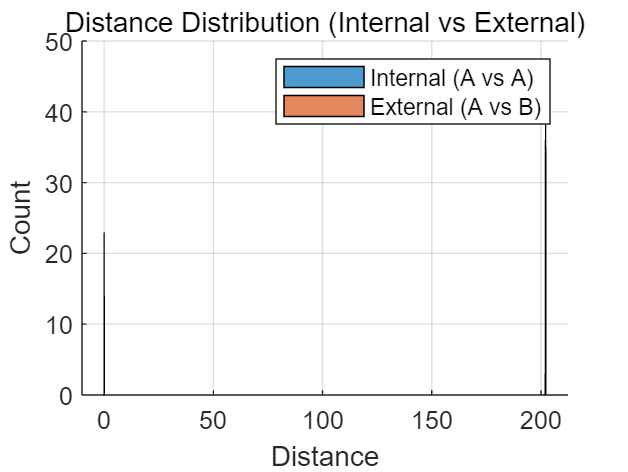



% ------------------------ 8. 图形可视化 ------------------------

figure; 
hold on;
histogram(InternalDistances, 20, 'FaceAlpha', 0.7);
histogram(ExternalDistances, 20, 'FaceAlpha', 0.7);
legend('Internal (A vs A)', 'External (A vs B)');
title('Distance Distribution (Internal vs External)');
xlabel('Distance');
ylabel('Count');
grid on;


disp(' ');

disp('🎉 所有分析已完成！');

🎉 所有分析已完成！


disp('==================================================');



% ------------------------ 5. 结果展示与统计 ------------------------

disp(' ');

disp('==================================================');

disp('            ✅ 综合特征分析报告 ✅');

            ✅ 综合特征分析报告 ✅


disp('==================================================');


T = cell2table(FinalResultsTable, 'VariableNames', {'Contrast', 'EuclideanDistance', 'Type'});
disp('--- 详细对比结果 (T 变量已保存在工作区) ---');

--- 详细对比结果 (T 变量已保存在工作区) ---


disp(T);

                                                                           Contrast                                                                            EuclideanDistance            Type         
    _______________________________________________________________________________________________________________________________________________________    _________________    _____________________

    {'E:\开放实验\语音库\LibriSpeech\dev-clean\1272\128104\1272-128104-0000.flac vs E:\开放实验\语音库\LibriSpeech\dev-clean\1272\128104\1272-128104-0001.flac'}        0.014925         {'Internal (A vs A)'}
    {'E:\开放实验\语音库\LibriSpeech\dev-clean\1272\128104\1272-128104-0000.flac vs E:\开放实验\语音库\LibriSpeech\dev-clean\1272\128104\1272-128104-0002.flac'}        0.029851         {'Internal (A vs A)'}
    {'E:\开放实验\语音库\LibriSpeech\dev-clean\1272\128104\1272-128104-0000.flac vs E:\开放实验\语音库\LibriSpeech\dev-clean\1272\128104\1272-128104-0003.flac'}        0.044776         {'Internal (A vs A)'}
    {'E:\开放实验\语音


% 统计分析
disp('--- 统计结果 (用于中期检查的关键数据) ---');

--- 统计结果 (用于中期检查的关键数据) ---



% 内部一致性统计
if ~isempty(InternalDistances)
    AvgInternal = mean(InternalDistances);
    MaxInternal = max(InternalDistances);
    disp(['[内部一致性] 总对比次数: ', num2str(length(InternalDistances))]);
    disp(['[内部一致性] 平均距离 (μ_intra): ', num2str(AvgInternal)]);
    disp(['[内部一致性] 最大距离: ', num2str(MaxInternal)]);
else
    AvgInternal = NaN;
    disp('[内部一致性] 未检测到有效距离。');
end

[内部一致性] 总对比次数: 105


[内部一致性] 平均距离 (μ_intra): 0.046908


[内部一致性] 最大距离: 0.13433




% 外部区分度统计
if ~isempty(ExternalDistances)
    AvgExternal = mean(ExternalDistances);
    MinExternal = min(ExternalDistances); 
    disp([' ']);
    disp(['[外部区分度] 总对比次数: ', num2str(length(ExternalDistances))]);
    disp(['[外部区分度] 平均距离 (μ_inter): ', num2str(AvgExternal)]);
    disp(['[外部区分度] 最小距离: ', num2str(MinExternal)]); 
else
    AvgExternal = NaN;
    disp('[外部区分度] 未检测到有效距离。');
end

[外部区分度] 总对比次数: 436


[外部区分度] 平均距离 (μ_inter): 202.1266


[外部区分度] 最小距离: 201.9675



% 区分度总结 (Inter vs Intra)
if ~isnan(AvgInternal) && ~isnan(MinExternal)
    disp([' ']);
    disp('--- 最终可行性证明 ---');
    if MinExternal > AvgInternal
        disp(['最小外部距离 (', num2str(MinExternal), ') > 平均内部距离 (', num2str(AvgInternal), ')']);
        disp('结论: **特征区分度高，项目可行性强。**');
    else
        disp('最小外部距离 <= 平均内部距离。');
        disp('结论: 特征区分度一般，建议在下一步优化预处理和特征归一化。');
    end
end

--- 最终可行性证明 ---


最小外部距离 (201.9675) > 平均内部距离 (0.046908)


结论: **特征区分度高，项目可行性强。**



% 导出结果到 CSV 文件 (方便报告记录)
writetable(T, 'Feature_Analysis_Report.csv', 'WriteVariableNames', true);
disp(' ');

disp('详细结果表格已导出到: Feature_Analysis_Report.csv');

详细结果表格已导出到: Feature_Analysis_Report.csv



% -------------------------------------------------------------------------
% 局部函数 (Local Functions) - 必须放在文件的最末尾
% -------------------------------------------------------------------------

% 辅助函数：递归查找文件夹中的音频文件

function file_list = find_audio_files_recursive(folder_path)
    file_list = {};
    
    % 获取当前文件夹内容
    d = dir(folder_path);
    
    for i = 1:length(d)
        name = d(i).name;
        
        % 跳过 '.' 和 '..'
        if strcmp(name, '.') || strcmp(name, '..')
            continue;
        end
        
        full_path = fullfile(folder_path, name);
        
        if d(i).isdir
            % 递归调用处理子文件夹
            sub_files = find_audio_files_recursive(full_path);
            file_list = [file_list, sub_files]; % 合并子文件夹的结果
        else
            % 检查是否是音频文件 (.wav 或 .flac)
            if endsWith(name, '.wav', 'IgnoreCase', true) || endsWith(name, '.flac', 'IgnoreCase', true)
                file_list = [file_list, {full_path}];
            end
        end
    end
end


% 辅助函数：提示用户输入文件或文件夹列表
function files = get_file_list(speaker_name)
    % 修正：使用 sprintf 将所有提示文本合并，确保所有信息在 input() 被调用时一同显示。
    prompt = sprintf([...
        '--- 请输入 "%s" 的音频文件或文件夹路径 (至少包含2个文件) ---\n', ...
        ' (可以输入多个路径，用英文逗号或空格隔开，例如: FolderA, D:\\Path\\B.wav)\n', ...
        '请输入路径列表: '], speaker_name);
        
    input_str = input(prompt, 's');
    
    input_paths = strsplit(input_str, {',', ' '}, 'CollapseDelimiters', true);
    input_paths = input_paths(~cellfun('isempty', input_paths)); % 移除空字符串

    files = {}; % 初始化最终的文件列表

    for i = 1:length(input_paths)
        current_path = strtrim(input_paths{i}); % 移除首尾空格

        if isfolder(current_path)
            % 如果是文件夹，递归查找音频文件
            audio_files_in_folder = find_audio_files_recursive(current_path);
            files = [files, audio_files_in_folder]; % 合并列表
        elseif isfile(current_path) && (endsWith(current_path, '.wav', 'IgnoreCase', true) || endsWith(current_path, '.flac', 'IgnoreCase', true))
            % 如果是单个音频文件，直接添加
            files = [files, {current_path}];
        else
            % 警告并跳过无法识别或不存在的路径
            warning(['路径不存在，或不是文件夹/支持的音频文件 (.wav/.flac): ', current_path]);
        end
    end
    
    % 检查是否收集到足够的文件
    if length(files) < 2
        error(['错误："', speaker_name, '" 至少需要包含 2 个有效音频文件。只找到 ', num2str(length(files)), ' 个。']);
    end

    fprintf('成功获取 %d 个 %s 的音频文件。\n', length(files), speaker_name);
end